myCellArray = createCellArrayFromDir("car/"); %1.1

now reading car\car_0000.jpg
now reading car\car_0001.jpg
now reading car\car_0002.jpg
now reading car\car_0003.jpg
now reading car\car_0004.jpg
now reading car\car_0005.jpg
now reading car\car_0006.jpg
now reading car\car_0007.jpg
now reading car\car_0008.jpg
now reading car\car_0009.jpg
now reading car\car_0010.jpg
now reading car\car_0011.jpg
now reading car\car_0012.jpg
now reading car\car_0013.jpg
now reading car\car_0014.jpg
now reading car\car_0015.jpg
now reading car\car_0016.jpg
now reading car\car_0017.jpg
now reading car\car_0018.jpg
now reading car\car_0019.jpg
now reading car\car_0020.jpg
now reading car\car_0021.jpg
now reading car\car_0022.jpg
now reading car\car_0023.jpg
now reading car\car_0024.jpg
now reading car\car_0025.jpg
now reading car\car_0026.jpg
now reading car\car_0027.jpg
now reading car\car_0028.jpg
now reading car\car_0029.jpg
now reading car\car_0030.jpg
now reading car\car_0031.jpg
now reading car\car_0032.jpg
now reading car\car_0033.jpg
now reading ca

kmeanedArray = KmeansOnCellArray(myCellArray,50);%1.2

filepath = ""

filepath = ""

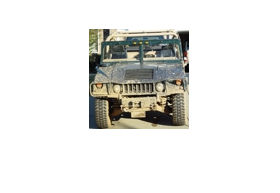

ImageNameArray = CreateNameArray("car_0000.jpg",kmeanedArray);%1.3

imshow(reconstructFromNameArray(ImageNameArray,0.25))%1.4


Repoduced =

     []



%%DOWNLOAD IMAGE MAIPULATION TOOLBOX! 

%Start för 1.5: return of the ssim, the tale of defeat

% read an image

inpict = imread('car_0000.jpg'); % 384x512x3

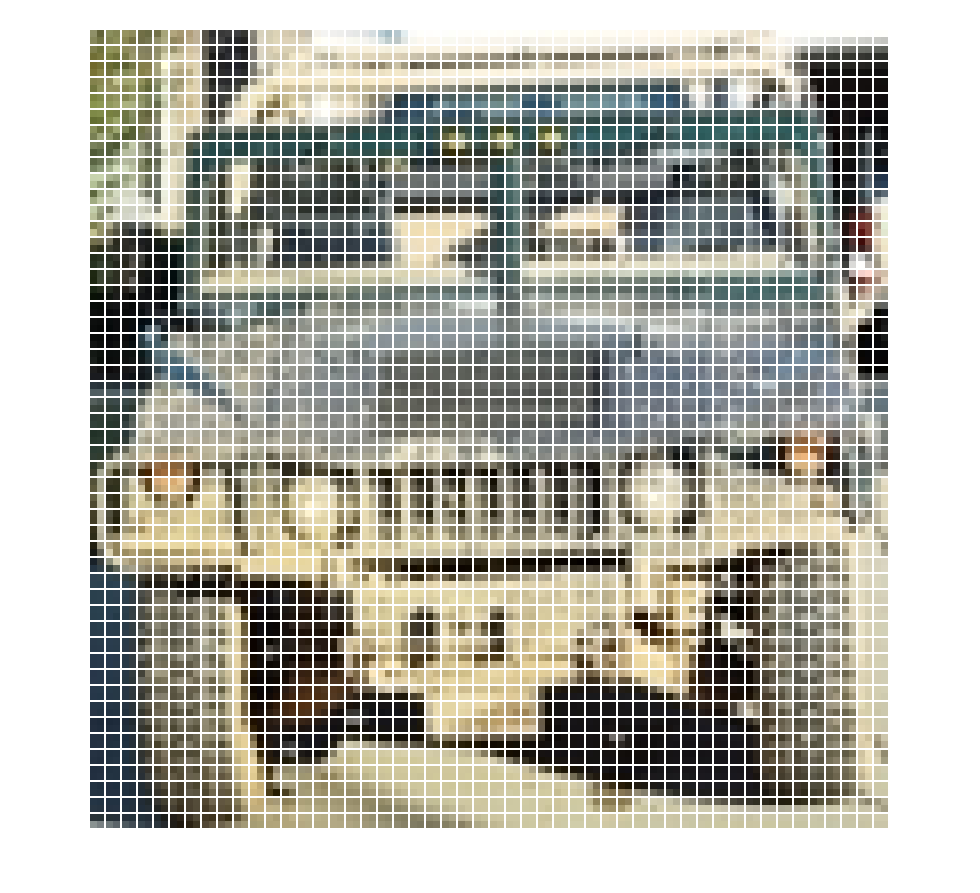

% split the image into 30 tiles in a 5x6 pattern
Nr_row = 50; %% HÄR BESTÄMMER NI HUR MÅNGA TILES DET SKA VARA Testa gärna med lite färre om ni ska köra 2500 tiles tar fan tid... 
tiling = [Nr_row Nr_row]; % [y x]
subimages = imdetile(inpict,tiling,'direction','row'); % 77x85x3x30


% show the result, adding padding for display clarity
montage(subimages,'size',tiling,'bordersize',[1 1],'backgroundcolor','w')

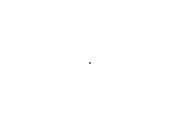

imshow(subimages(:,:,:,1)) %%one tile, just need to loop all the tiles :D 


test = im2double(inpict);

%Kort test för att se så att skalan blir rätt... 2x2 pixlar ger inte så
%mycket info 
testTile = im2double(subimages(:,:,1,1));
scale = length(testTile)/length(inpict)

scale = 0.0200

test = imresize(test,scale,"bicubic");

ssim(testTile,test(:,:,1))

ans = 0.1261


Repoduced =

     []



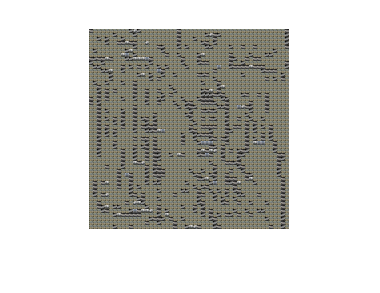


valueBestMatch = 0;
nameOfBestMatch  ="";
ssimNameArray = strings;

%jag vet att det här ser lite bökigt ut men jag går egentligen igenom varje
%tile och kollar vilken bild i databasen som ger bäst Ssim. 
%problemet är lite att jag måste skala om bilderna i databasen till 2x2 px
%vilket är ganska useless, därför skulle jag behöva en mer högupplöst bild
%än 100x100 så att struktuerna faktistk går att urskilja, sen kanske vi
%skulle behöva en roligare bilddatabas. 

%lite av kruxet är ju att det färg gör mer än struktur var gällande
%reproduktion så det vi egentligen skulle behöva göra är att ta dom färger
%som är närmast och välja ur dom baserat på ssim
%optimalt bör tilesn vara samma dimensioner som en bild på en bil (där man
%faktiskt kan se bilen...)

for i = 1:Nr_row^2
    for k = 1:length(kmeanedArray)
   
        currentImg = cell2mat(kmeanedArray{k}(1,3));
        testTile = im2double(subimages(:,:,1,1));% just one Tile
    
        scale = length(testTile)/length(currentImg);
        currentImg = imresize(currentImg,scale,"bicubic");
        
        
        %Kommentera bort detta sen, ville bara testa om resultatet blev
        %annorluna om vi körde sim på LAB, egentligen borde L väga mer än
        %ab i detta fall men har inte hunnit testa runt än 
%         currentImg = rgb2lab(currentImg);
%         testTile = rgb2lab(testTile)
    
    
        R = ssim(im2double(subimages(:,:,1,i)),currentImg(:,:,1));
        G = ssim(im2double(subimages(:,:,2,i)),currentImg(:,:,2));
        B = ssim(im2double(subimages(:,:,3,i)),currentImg(:,:,3));
      totalAvg= (R+G+B)/3;
        if valueBestMatch<totalAvg
                    valueBestMatch = deltaE;
                    nameOfBestMatch = string(kmeanedArray{k}(1));
        end
    
    
    
    
    
    end 
    row = mod(i-1,Nr_row)+1;
    col = ceil(i/Nr_row);
    sep ="";
    ssimNameArray(row,col) = nameOfBestMatch;
    valueBestMatch=0;
    
end

%som ni ser av resultatet så är det här inge vidare, kanske att vi skulle
%få en bättre match om vi körde på en mer högupplöst bild tänk typ
%1000x1000
imshow(reconstructFromNameArray(ssimNameArray,scale))